# RADAR MODEL

This code illustrates a method for finding the delay between two signals.

close all;
clear all;
clc;

The signal is constructed with given parameters.

Fs = 1e5;  % Sampling frequency
dt = 1/Fs; % Sampling period
Range = 1000; % Range
signal_length = 8e-3; % Signal length
antenna_gain = 20; % Antenna gain in dB
rcs = 0.1; % Radar cross section
Time = 0.05; % Half time axis lengh
light_speed = physconst("LightSpeed"); % Light speed
dt_div = 1000; % Division of dt for cross correlation
fc = 1e4; % Operating frequency
t = -Time:dt:Time; % Time scale
transmitter_power = 100; % Signal power

Transmitted sinusoidal pulse signal

window = 1*(t>=0 & t<=signal_length); % Original signal width
signal_model = sin(2*pi*fc*t).*window; % Original sinusoidal pulse signal
transmitter_amp_square = sum(signal_model.^2)/(length(window)*transmitter_power);
signal = signal_model/sqrt(transmitter_amp_square);

Delay, loss and noise are added and the received signal is constructed.

free_spl = (4*pi*Range*fc/light_speed)^2; % Free space path loss
antenna_gain_p = db2pow(antenna_gain); % Antenna gain in power
loss = antenna_gain_p^2*rcs/(free_spl*4*pi*Range^2); % Total loss from radar equation
tpower = sum(signal.^2)/length(window) % Transmitted signal power

tpower = 100.0000

rpower = tpower*loss % Received signal power

rpower = 0.0453

receiver_amp_square = sum(signal_model.^2)/(length(window)*rpower);
delay = -2*Range/light_speed % Delay of received signal

delay = -6.6713e-06

window_del = 1*((t+delay)>=0 & (t+delay)<=signal_length); % Delayed signal width
signal_del = sin(2*pi*fc*(t+delay)).*window_del; % Delayed sinusoidal pulse signal
signal_del = signal_del/sqrt(receiver_amp_square);
receiver_power = sum(signal_del.^2)/length(window) 

receiver_power = 0.0453

signal_del1 = awgn(signal_del,0,"measured"); % Noise
power_first = sum((signal_del1-signal_del).^2)/length(t)

power_first = 0.0451

power_sig = sum((signal_del).^2)/length(window_del);
10*log10(power_sig/power_first)

ans = 0.0150

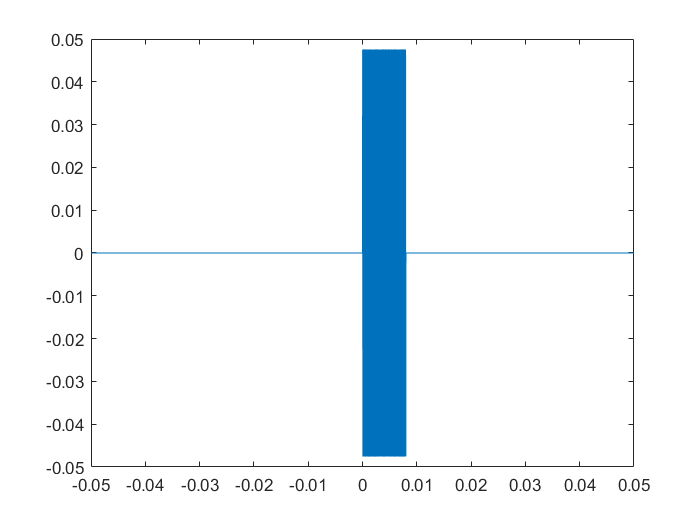

matched_filter = eye(length(t))*signal'/sqrt(signal*eye(length(t))*signal');
figure;
plot(t,matched_filter);

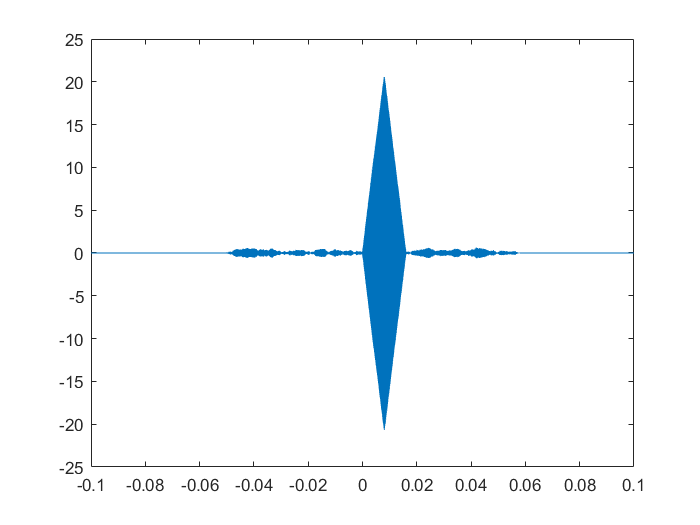

x = conv(signal_del1,matched_filter);
tt = -2*Time:dt:2*Time; % Time scale
figure;
plot(tt,x);

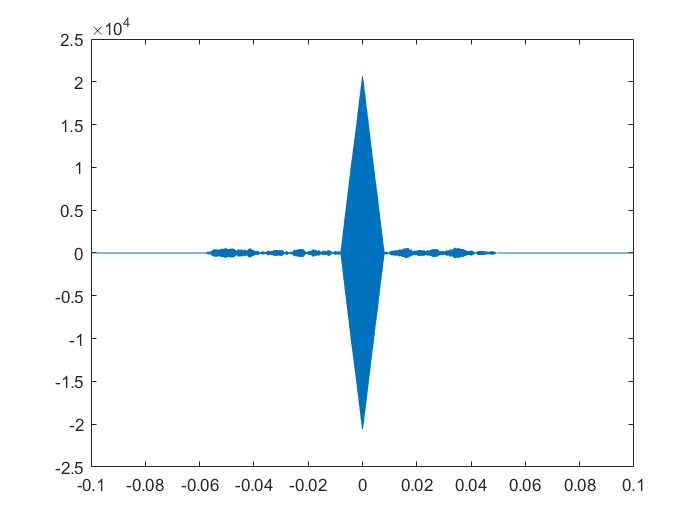

h = signal(end:-1:1);
aft = conv(signal_del1,h);
figure;
plot(tt,aft);

 The signals are plotted.

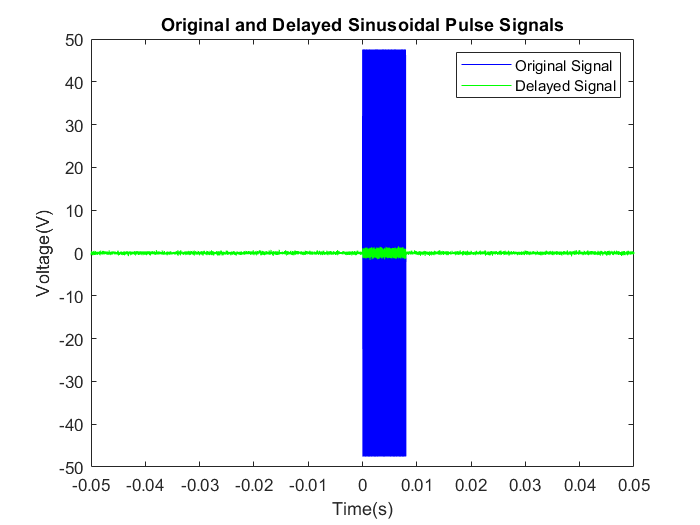

figure;
plot(t,signal,"Color","b"); 
hold on;
plot(t, signal_del1,"Color","g");
title("Original and Delayed Sinusoidal Pulse Signals");
legend("Original Signal","Delayed Signal");
xlabel("Time(s)");
ylabel("Voltage(V)");

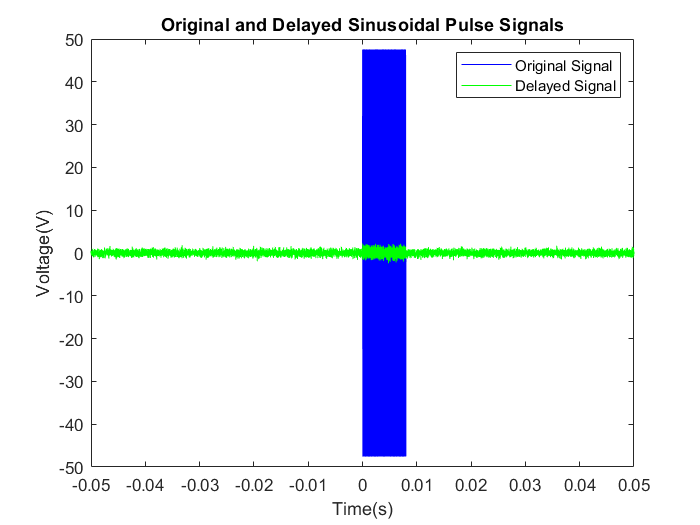

signal_del2 = signal_del + 0.5*randn(1,length(t)); % Noise
figure;
plot(t,signal,"Color","b"); 
hold on;
plot(t, signal_del2,"Color","g");
title("Original and Delayed Sinusoidal Pulse Signals");
legend("Original Signal","Delayed Signal");
xlabel("Time(s)");
ylabel("Voltage(V)");

power_second = sqrt(sum((signal_del2-signal_del).^2)/length(t))

power_second = 0.5049

To find the fractional delay, cross correlation is used. Both auto and cross correlations are computed and the highest value of the cross correlation is found. Then, the index of this value is obtained, which is the delay time.

[cross_cor,t_cor] = xcorr(signal,signal_del1); % Cross correlation of the original and delayed signals
[auto_cor,t_acor] = xcorr(signal); % Auto correlation of the original signal

Both auto and cross correlations are plotted.

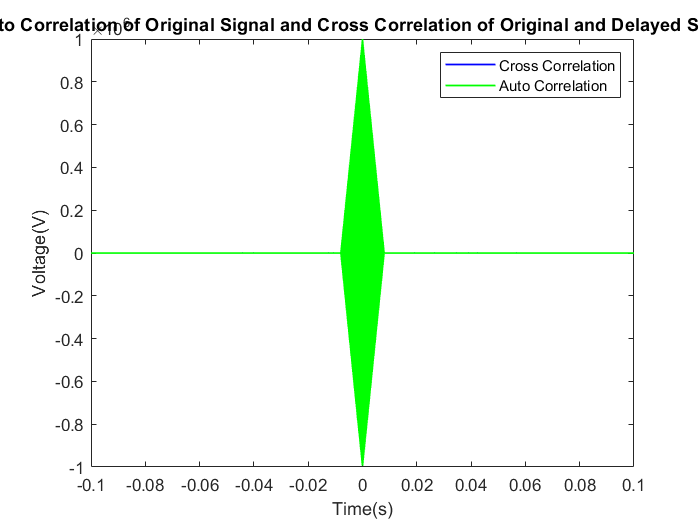

% Plots of the auto correlation and cross correlation functions
figure;
plot(t_cor/Fs,cross_cor,"LineWidth",1,"Color","b");
hold on;
plot(t_acor/Fs,auto_cor,"LineWidth",1,"Color","g");
title("Auto Correlation of Original Signal and Cross Correlation of Original and Delayed Signals");
legend("Cross Correlation","Auto Correlation");
xlabel("Time(s)");
ylabel("Voltage(V)");

Peak value of the cross correlation is found with the index.

[pk,i] = max(cross_cor); % Peak value and index value of the peak for cross correlation function 
x_value = t_cor/Fs;
del = x_value(i)

del = -1.0000e-05

As can be seen, this value is only the unit part of the delay. To compute the fractional part, first, the original signal is delayed by the unit part. Then, the cross correlation is computed in a single sampling period by dividing this range to small parts and the delay is obtained in a similar way as before.

unit = finddelay(signal,signal_del1) % Unit part of the delay

unit = 1

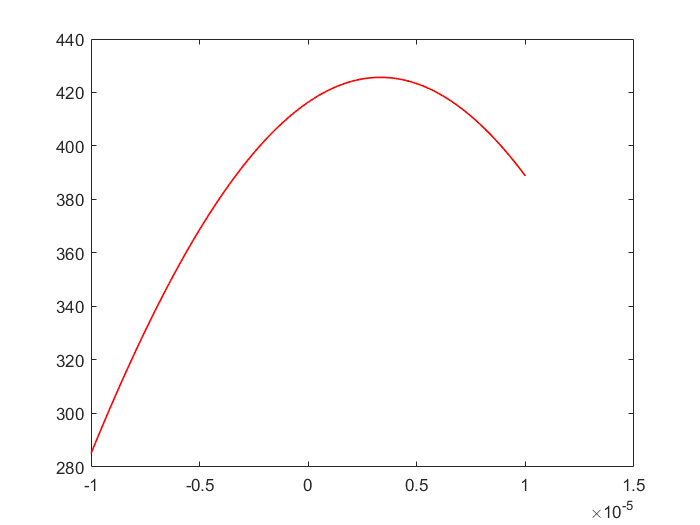

% window = 1*((t+del)>=0 & (t+del)<=8e-3); 
% signal = sin(2*pi*fc*(t+del)).*window; % Original signal is delayed according to the unit found 

% Finding the cross correlations in small interval for fractional delay
% computation
correlation_values = [];
for mini_delays = -dt:dt/dt_div:dt
    window_mini_del = 1*((t+del+mini_delays)>=0 & (t+del+mini_delays)<=signal_length);
    signal_mini_del = sin(2*pi*fc*(t+del+mini_delays)).*window_mini_del;
    cor_value = sum(signal_mini_del.*signal_del);
    correlation_values = [correlation_values;cor_value];
end
mini_delays = -dt:dt/dt_div:dt;

% Plot of the cross correlation values
figure;
plot(mini_delays,correlation_values,"LineWidth",1,"Color","r");

[pk,i] = max(correlation_values); % Peak value of the cross correlation and its index
dell = mini_delays(i) % Fractional delay

dell = 3.3300e-06

delll = dell + del

delll = -6.6700e-06

rang = light_speed*abs(delll)/2

rang = 999.8078

Although the code can find the delay very precisely, it is not sufficient since it cannot solve the ambiguity in angle. For this purpose, the IQ data is used.

## IQ DATA

I data and Q data values are found.

q_data = 2*signal_del.*cos(2*pi*fc*t)/received_signal_amp; % Q Data
i_data = 2*signal_del.*sin(2*pi*fc*t)/received_signal_amp; % I Data

Their plots

% Plot of Q Data
figure; 
subplot(3,2,1)
plot(t,q_data,"LineWidth",1,"Color","b");
title("Q Data");
xlabel("Time(s)")
ylabel("Voltage(V)")

% Plot of I Data
subplot(3,2,2)
plot(t,i_data,"LineWidth",1,"Color","b");
title("I Data");
xlabel("Time(s)")
ylabel("Voltage(V)")

The FFT of the signals are found to observe the frequency characteristics.

fft_q_data = fft(q_data); %FFT of Q Data
freq_scale = linspace(0,Fs,length(t)); % Frequency scale of FFT
% Plot of absolute
subplot(3,2,3)
plot(freq_scale,abs(fft_q_data)/length(t),"LineWidth",1,"Color","b");
title("FFT of Q Data")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

fft_i_data = fft(i_data); %FFT of I Data

% Plot of absolute
subplot(3,2,4)
plot(freq_scale,abs(fft_i_data)/length(t),"LineWidth",1,"Color","b");
title("FFT of I Data")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

% Plot of shifted FFT of Q Data
shifted_freq_scale = linspace(-Fs/2,Fs/2,length(t)); % Shifted frequency scale
subplot(3,2,5)
plot(shifted_freq_scale,fftshift(abs(fft_q_data)/length(t)),"LineWidth",1,"Color","b");
title("Shifted FFT of Q Data")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

% Plot of shifted FFT of I Data
subplot(3,2,6)
plot(shifted_freq_scale,fftshift(abs(fft_i_data)/length(t)),"LineWidth",1,"Color","b");
title("Shifted FFT of I Data")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

The signals are passed from a lowpass filter to obtain the angle. Finding the valus of the Q and I Data and then calculating the angle. From there, the delay of the signal can be calculated.

low_pass_filter = designfilt("lowpassfir","FilterOrder",128,"DesignMethod","maxflat","HalfPowerFrequency",fc*0.07,"SampleRate",Fs);
% fvtool(low_pass_filter,"MagnitudeDisplay","magnitude")
q_data_filtered = filter(low_pass_filter,q_data); % Sine theta
i_data_filtered = filter(low_pass_filter,i_data); % Cosine theta 
% q_data_filtered = lowpass(q_data,0.0001*fc,Fs); % Sine theta
% i_data_filtered = lowpass(i_data,0.0001*fc,Fs); % Cosine theta 

% Plot of Q Data after filtering
figure;
subplot(3,2,1)
plot(t,q_data_filtered,"LineWidth",1,"Color","b");
title("Q Data after Lowpass Filtering")
xlabel("Time(s)")
ylabel("Voltage(V)")

% Plot of I Data after filtering
subplot(3,2,2)
plot(t,i_data_filtered,"LineWidth",1,"Color","b");
title("I Data after Lowpass Filtering")
xlabel("Time(s)")
ylabel("Voltage(V)")

% FFT of Q Data after filtering
fft_q_data_filtered = fft(q_data_filtered); % FFT

% FFT of I Data after filtering
fft_i_data_filtered = fft(i_data_filtered); % FFT

% Plot of absolute after filtering Q Data
subplot(3,2,3)
plot(freq_scale,abs(fft_q_data_filtered)/length(t),"LineWidth",1,"Color","b");
title("FFT of Q Data after Filtering")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

% Plot of absolute after filtering I Data
subplot(3,2,4)
plot(freq_scale,abs(fft_i_data_filtered)/length(t),"LineWidth",1,"Color","b");
title("FFT of I Data after Filtering")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

% Plot of shifted FFT after filtering Q Data
subplot(3,2,5)
plot(shifted_freq_scale,fftshift(abs(fft_q_data_filtered)/length(t)),"LineWidth",1,"Color","b");
title("Shifted FFT of Q Data after Filtering")
xlabel("Frequency(Hz)")
ylabel("Amplitude")

% Plot of shifted FFT after filtering I Data
subplot(3,2,6)
plot(shifted_freq_scale,fftshift(abs(fft_i_data_filtered)/length(t)),"LineWidth",1,"Color","b");
title("Shifted FFT of I Data after Filtering")
xlabel("Frequency(Hz)")
ylabel("Amplitude")  
% k = nonzeros(q_data_filtered);
% l = nonzeros(i_data_filtered);
% 
% sine_theta = k(round(length(k)/2))
% theta = asin(sine_theta)
% % del = theta/(2*pi*fc)
% cosine_theta = l(round(length(k)/2))
% theta1 = acos(cosine_theta)
% del = theta/(2*pi*fc)
% del1 = theta1/(2*pi*fc)